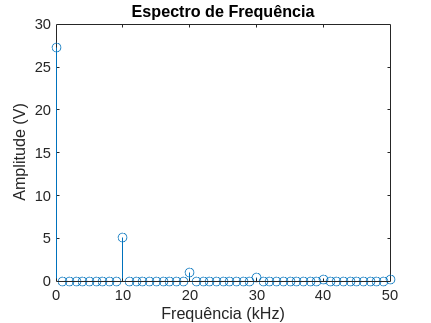

%% Seção 2 - Análise Espectral (Executar após Seção 1)
load('dados_sinal.mat', 'y_ret', 'Fs', 't'); 

N = length(y_ret);
if mod(N,2) ~= 0
    N = N - 1; % Garante N par
    y_ret = y_ret(1:N);
end

Y = fft(y_ret)/N;
freq = Fs*(0:(N/2))/N;
amplitude = 2*abs(Y(1:N/2+1));

figure;
stem(freq/1000, amplitude);
xlim([0 50]);
xlabel('Frequência (kHz)');
ylabel('Amplitude (V)');
title('Espectro de Frequência');
saveas(gcf, 'Espectro_Frequencia.png');